# **Pràctica 8: Sistemes d'equacions NO lineals**

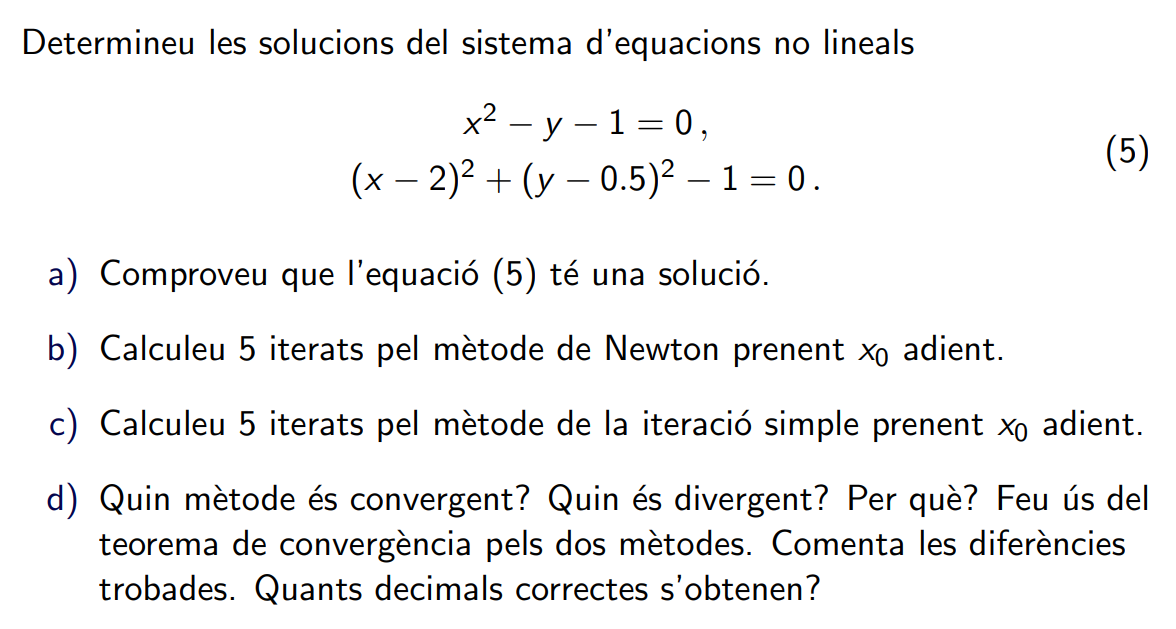

a)

f = @(x)x.^2-1

f = function_handle with value:
    @(x)x.^2-1


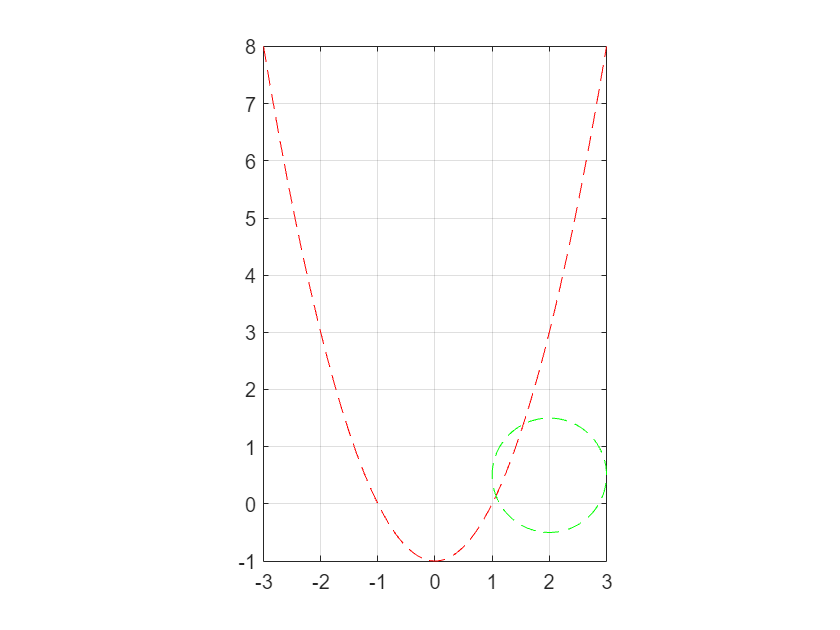

fplot(f, [-3,3], 'r--')
hold on
theta = 0:0.01:2*pi; % Rango de valores para theta
r = 1; % Radio
h = 2; % Coordenada x del centro
k = 0.5; % Coordenada y del centro

x = h + r*cos(theta); % Coordenadas x en la circunferencia
y = k + r*sin(theta); % Coordenadas y en la circunferencia

plot(x,y, 'g--');
axis equal;
grid on;
hold off

b)

x0 = [0 0]'

x0 =      0
     0


f = @(X)X(1).^2-X(2)-1

f = function_handle with value:
    @(X)X(1).^2-X(2)-1


g = @(X)(X(1)-2).^2 + (X(2)-0.5)^2 -1

g = function_handle with value:
    @(X)(X(1)-2).^2+(X(2)-0.5)^2-1


F = @(X) [f(X);g(X)]

F = function_handle with value:
    @(X)[f(X);g(X)]


fx = @(X)2.*X(1)

fx = function_handle with value:
    @(X)2.*X(1)


fy = @(X)-1

fy = function_handle with value:
    @(X)-1


gx = @(X)2.*(X(1)-2)

gx = function_handle with value:
    @(X)2.*(X(1)-2)


gy = @(X)2.*(X(2)-0.5)

gy = function_handle with value:
    @(X)2.*(X(2)-0.5)


J = @(X)[fx(X), fy(X); gx(X), gy(X)]

J = function_handle with value:
    @(X)[fx(X),fy(X);gx(X),gy(X)]


x = [1 0]'

x =      1
     0


F(x)

ans =          0
    0.2500


while (norm(x - x0) >= 0.5*10^-5 & norm(F(x)) >= 0.5*10^-5)
    x0 = x;
    x = x - (J(x)\F(x));
    x
end

x =     1.0625
    0.1250


x =     1.0673
    0.1391


x =     1.0673
    0.1392


fsolve(F, [0,0]')


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =     1.0673
    0.1392
